# Dataset visualizer

dataset_path='C:\VegetationData\hif_vegetation_dataset.h5'

dataset_path = 'C:\VegetationData\hif_vegetation_dataset.h5'

Visualizing groups and attributes

h5info(dataset_path).Groups

ans = 2×1 struct array with fields:
    Name
    Groups
    Datasets
    Datatypes
    Links
    Attributes


h5info(dataset_path).Groups(1).Groups

ans = 53×1 struct array with fields:
    Name
    Groups
    Datasets
    Datatypes
    Links
    Attributes


h5info(dataset_path).Groups(1).Groups(1).Attributes

ans = 2×1 struct array with fields:
    Name
    Datatype
    Dataspace
    Value


h5info(dataset_path).Groups(2).Groups

ans = 983×1 struct array with fields:
    Name
    Groups
    Datasets
    Datatypes
    Links
    Attributes


h5info(dataset_path).Groups(2).Groups(300).Attributes

ans = 4×1 struct array with fields:
    Name
    Datatype
    Dataspace
    Value


Visualizing waveforms

test_number = 335;

disp(sprintf('Test number - %d',test_number))

Test number - 335


disp(sprintf('Fault type - %s',h5readatt(dataset_path,strcat('/test/',num2str(test_number)),'fault_type')))

Fault type - bush


disp(sprintf('Max set current - %d A',h5readatt(dataset_path,strcat('/test/',num2str(test_number)),'max_current')))

Max set current - 4 A


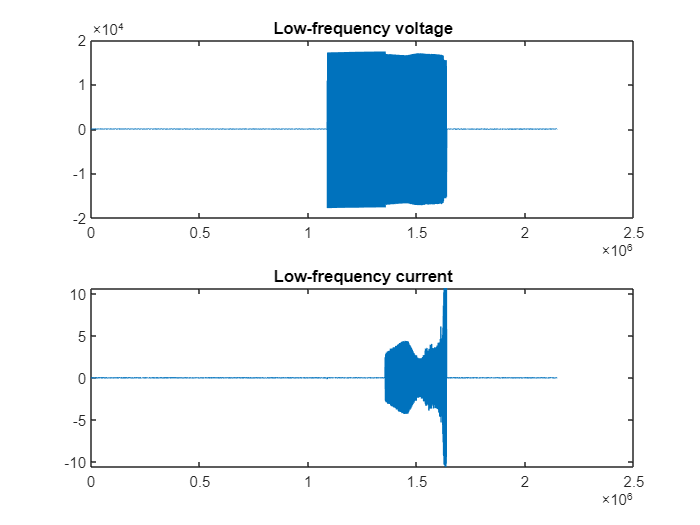


voltage_lf = h5read(dataset_path,strcat('/test/',num2str(test_number),'/voltage_lf'));
current_lf = h5read(dataset_path,strcat('/test/',num2str(test_number),'/current_lf'));
figure;
subplot(2,1,1)
plot(voltage_lf)
title('Low-frequency voltage')
subplot(2,1,2)
plot(current_lf)
title('Low-frequency current')

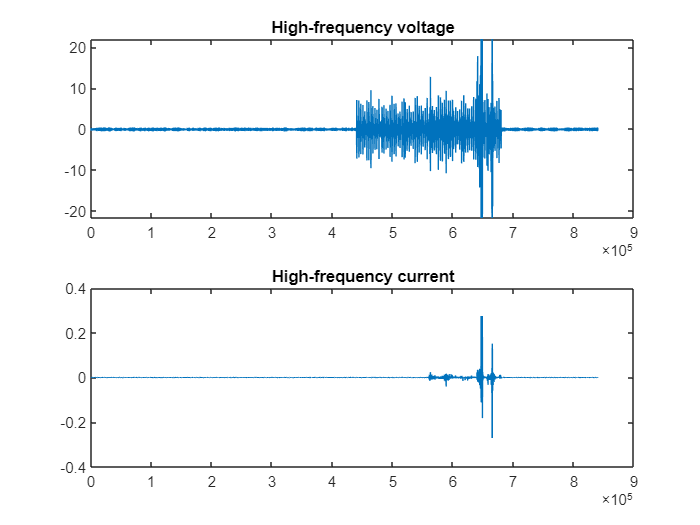

voltage_hf = h5read(dataset_path,strcat('/test/',num2str(test_number),'/voltage_hf'));
current_hf = h5read(dataset_path,strcat('/test/',num2str(test_number),'/current_hf'));
figure;
subplot(2,1,1)
plot(voltage_hf)
title('High-frequency voltage')
subplot(2,1,2)
plot(current_hf)
title('High-frequency current')

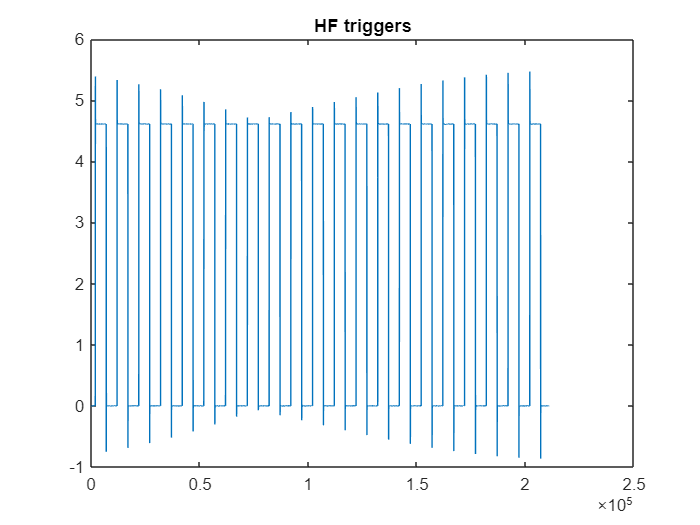

hf_triggers = h5read(dataset_path,strcat('/test/',num2str(test_number),'/hf_trigger'));
figure;
plot(hf_triggers)
title('HF triggers')